# Why the 3dB bandwidth of an un-modulated pulse of duration is $\frac{1}{\tau }$

First, the meaning of 3dB bandwidth is the magnitude that the value become 50% of its original value.

If the signal is half sine wave and the frequency is changing then...

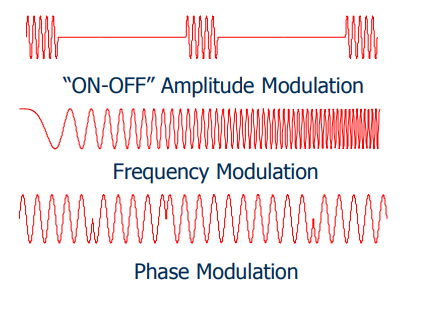

## Q. Fourier Transform of the signal $\mathrm{sin}\left(x\right)\;\mathrm{when}\;|x|<\frac{\pi }{2}$ Otherwise 0

#### Definition of FTransform 

Fourier Transform transform a time signal to a frequency component function. When time function is transformed then this becomes a complex function and the magnitude of this becomes the amount of frequency component contained inside the original function. and the phase angle becomes the difference between the sine function.

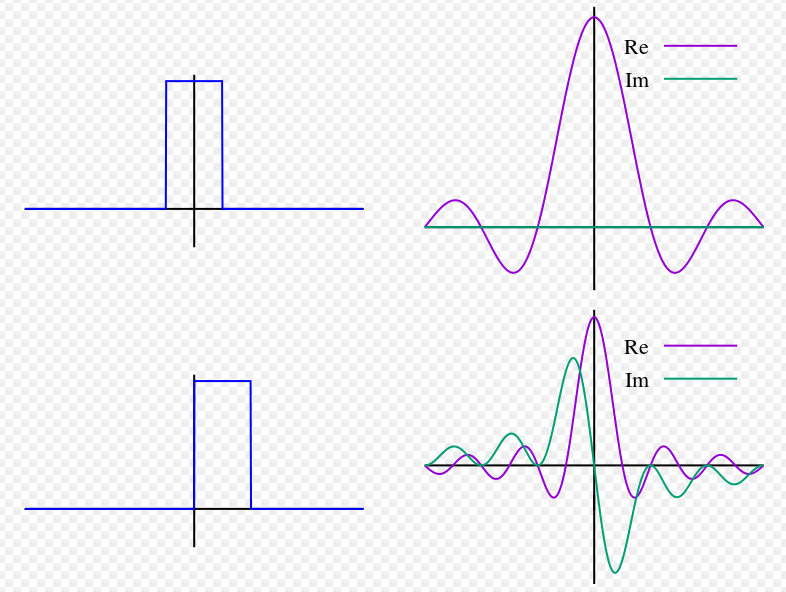

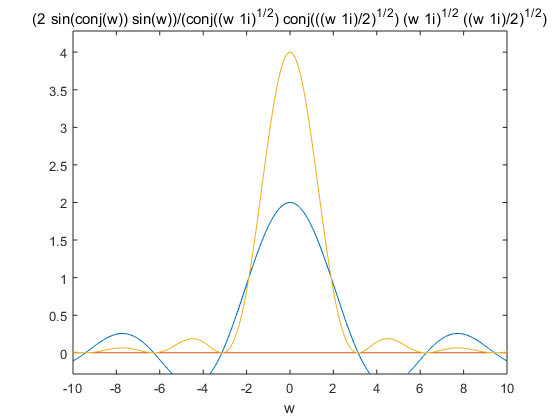

syms x w;
f = int(exp(-i*w*x),-1,1);
g = f*conj(f);
figure(1);
ezplot(real(f),[-10 10]);
hold on;
ezplot(imag(f),[-10 10])
ezplot(g,[-10 10]);
hold off;


$$X\left(w\right)=\int_{-\infty }^{\infty } x\left(t\right)e^{-\mathrm{jwt}} \mathrm{dt}$$
 


$$x\left(t\right)=\frac{1}{2\pi }\int_{-\infty }^{\infty } X\left(w\right)e^{\mathrm{jwt}} \mathrm{dw}$$


if the function is like this then

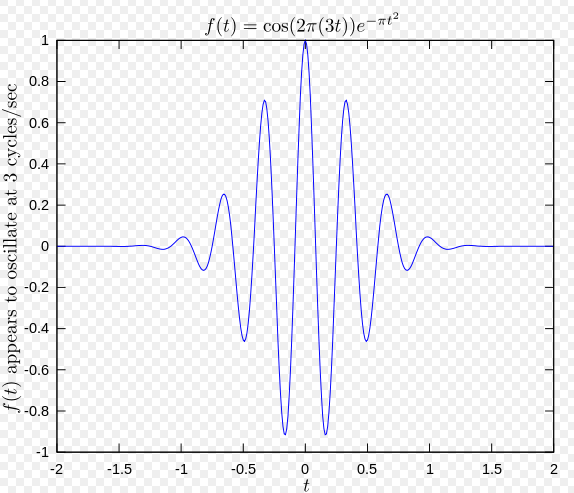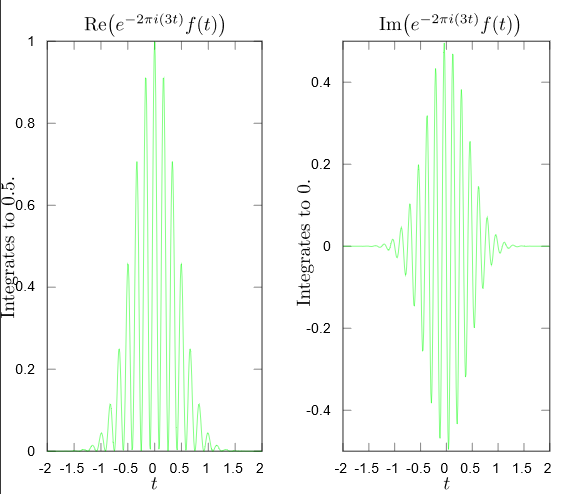

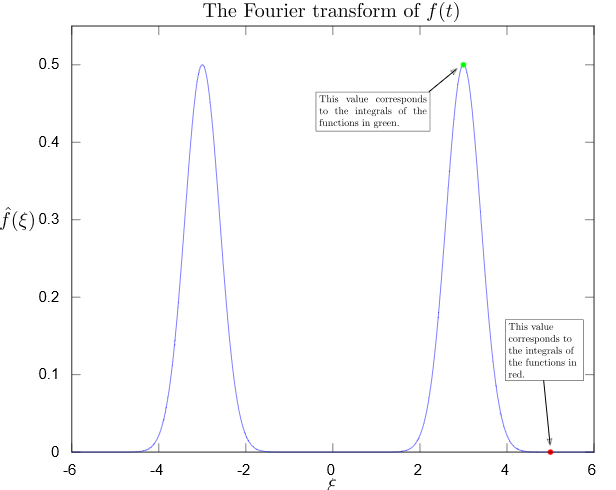

#### Therefore, according to the definition, $X\left(w\;\right)=\;\int_{-\pi }^{\pi } \sin \left(x\right)e^{-\textrm{jwx}} \textrm{dx}$

syms X(w) xb(x) magX(w) xa(x) x w
xa(x) = piecewise(x > -pi, sin(x),x < pi, sin(x), 0)

$$xa(x) = \left\{ \begin{array}{cl} \sin\left(x\right) & \text{ if }x\in \mathbb{R}\\ 0 & \mathrm{otherwise} \end{array}\right.$$

X(w) = int(exp(-i*w*x),x,-1,1) % Period is 2 therefore, 1/2 = 0.5 a     nd 1 is NULL TO NULL

$$X(w) = \frac{\sqrt{2}\,\sin\left(w\right)\,\mathrm{i}}{\sqrt{w\,\mathrm{i}}\,\sqrt{\frac{w\,\mathrm{i}}{2}}}$$

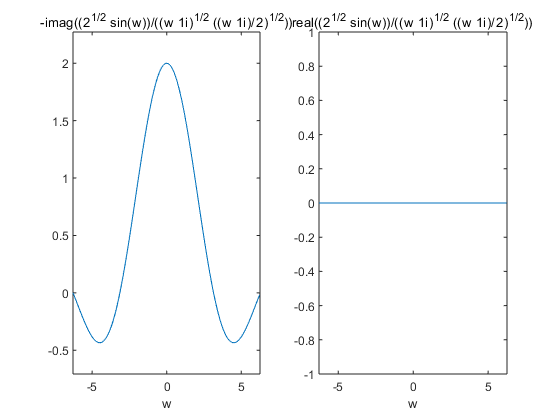

subplot(1,2,1);
ezplot(real(X))
subplot(1,2,2);
ezplot(imag(X))

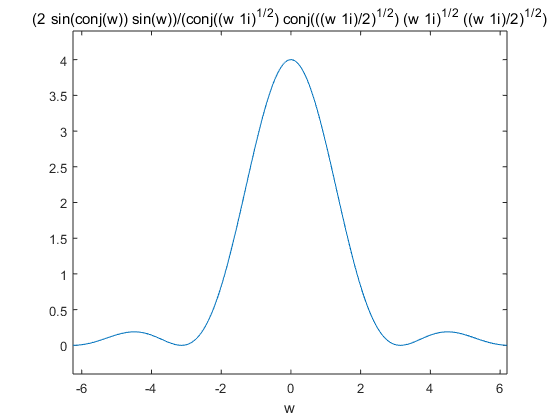

figure(5);
ezplot(X*conj(X))

bandwidth = 2/(2)

bandwidth = 1

%find w that make the mag 0
%x = [0:0.01:3];
%aa = matlabFunction(magX);
%aa(x)

So, Back to our question why the 3dB bandwith of a unmodulated signal , the pulse duration is $\frac{1}{\tau }$ ?

In above example the pulse width is $\pi$  NULL TO NULL bandwidgh is $\frac{1}{\pi }=0\ldotp 3183$

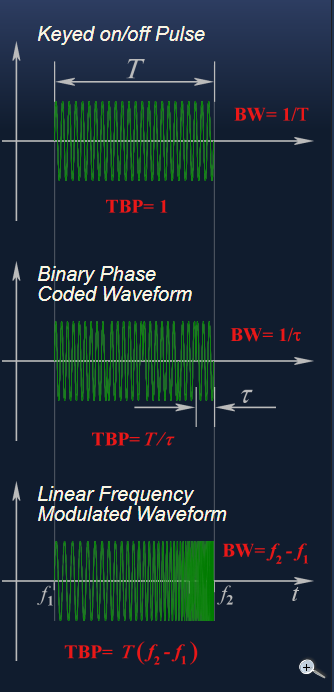

Things need to be proved..

%Fourier Transform
%int(sin(x)*exp(-i*w*t),-inf,inf)

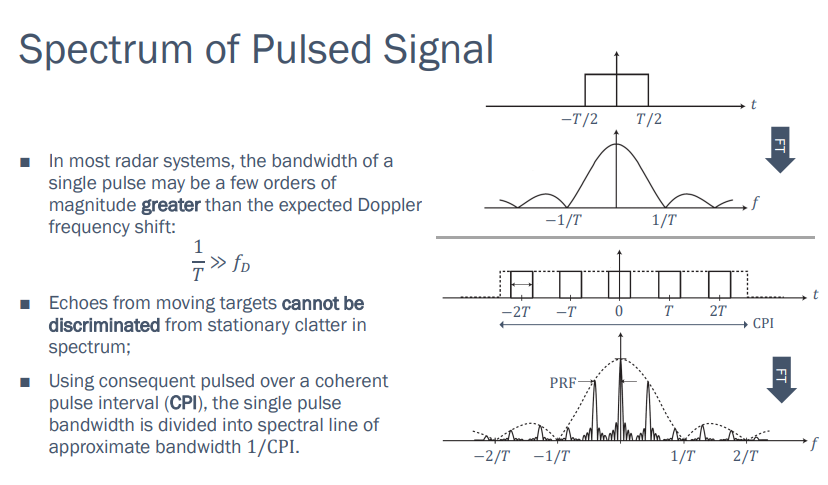

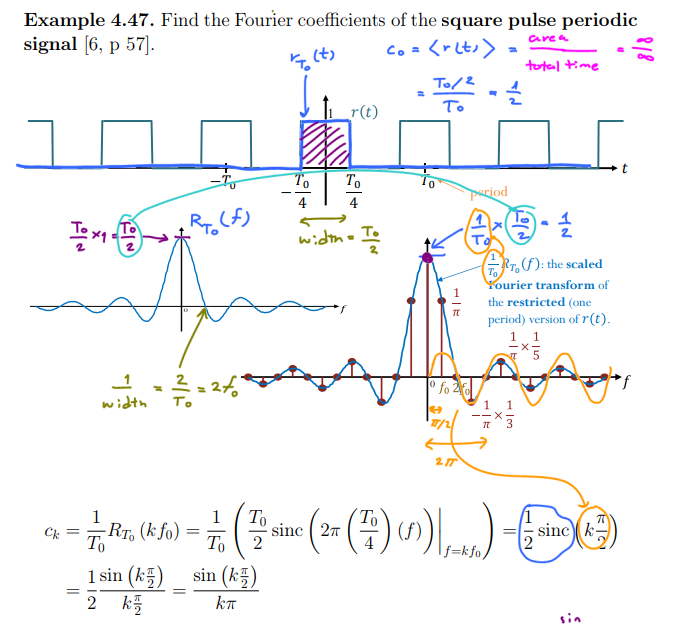

maybe it means something like this ??

We can use Fourier Series 

## $C_m =\frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} f\left(t\right)e^{-{\textrm{jmtw}}_0 } \textrm{dt}$ we wiil use this formulae to check

T = 2 and the wave is square wave 

Like the graph above

syms x y z w n t;
width = t;
t = 3

t = 3

re = int(1*exp(-j*n*pi*x),x,-0.5,0.5)/2

$$re = \frac{\sin\left(\frac{\pi \,n}{2}\right)}{n\,\pi }$$

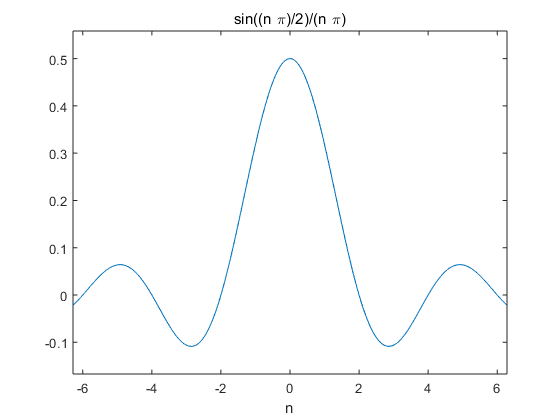

figure(7);
ezplot(re);

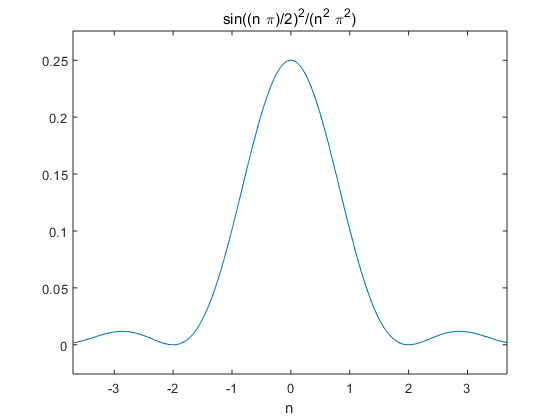

ezplot(re^2);

figure(6);
%plot([-10 :1 :10],cm([-10 :1: 10]));


We prove that NULL to NULL range is $\frac{2}{\tau }\;$which in this case is 4  


$$\begin{array}{l}
f\left(x\right)\;=1\;\;\;\mathrm{where}-T<x<T\\
\mathrm{else}\;\;f\left(x\right)=0
\end{array}$$


#### F transform $f\left(w\right)=\int_{-\infty }^{\infty } f\left(t\right)e^{-\mathrm{jwt}} \mathrm{dt}$

syms w t;
fw = int(exp(-j*2*pi*w*t),t,-1,1)

$$fw = \frac{\sqrt{2}\,\sin\left(2\,\pi \,w\right)\,\mathrm{i}}{\pi \,\sqrt{w\,\mathrm{i}}\,\sqrt{2\,w\,\mathrm{i}}}$$

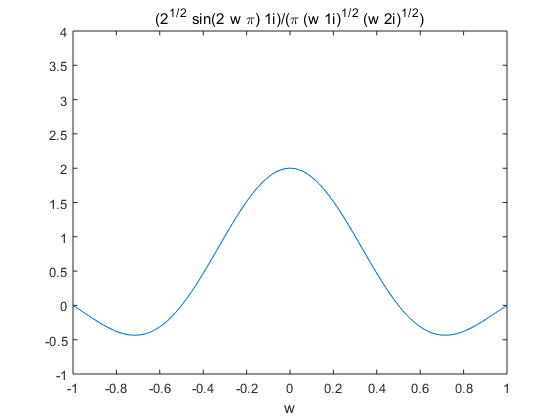

ezplot(fw,[-1 1 -1 4]);

We know that the null to null band width is 1

Which is smae as $\frac{2}{2}$

It turns out it is ture

syms w t;
fw = int(exp(-j*2*pi*w*t),t,0,2)

$$fw = \frac{\left({\mathrm{e}}^{-4\,\pi \,w\,\mathrm{i}}-1\right)\,\mathrm{i}}{2\,w\,\pi }$$

mw = sqrt( fw*conj(fw) )

$$mw = \frac{\sqrt{\frac{\left({\mathrm{e}}^{4\,\pi \,\bar{w}\,\mathrm{i}}-1\right)\,\left({\mathrm{e}}^{-4\,\pi \,w\,\mathrm{i}}-1\right)}{4\,w\,\bar{w}}}}{\pi }$$

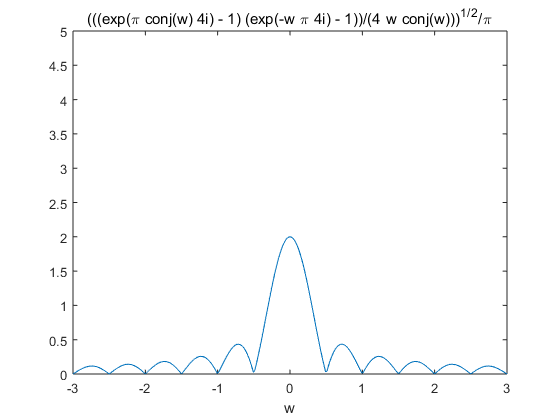

ezplot(mw,[-3 3 0 5])